**🔬 Motivation**

In inverse problems and parameter identification, it is often necessary to understand how the outputs of a model respond to small changes in the model’s parameters. This process (known as **sensitivity analysis) **involves computing derivatives of the output (e.g., stress, displacement, voltage) with respect to the parameters (e.g., elastic moduli, conductivities, etc.). These derivatives are fundamental to building Jacobians, Fisher Information Matrices, and assessing identifiability or stability of parameter estimation.

This script illustrates these ideas in a simple, well-understood setting: fitting a quadratic polynomial $y={\textrm{ax}}^2 +\textrm{bx}+c$ to noisy data. This mirrors the process used in more complex systems, such as nonlinear hyperelastic constitutive laws, where sensitivity with respect to material parameters is crucial for experimental design and model calibration.

**🧠 Conceptual Distinction**

This example also highlights an important distinction: while parameters are **held constant** during forward simulations or evaluations (as required in constitutive modeling and mechanics), it is entirely consistent to compute **derivatives with respect to those parameters** in order to assess how sensitive or identifiable they are during inverse analyses. This distinction is central to the methodology used in our paper, where we use such derivatives to design experiments that produce repeatable and accurate parameter estimations.

In summary, this script offers a minimal yet powerful demonstration of:

- The impact of input sampling on conditioning and estimation quality,

- The rationale for parameter sensitivity analysis,

- The mathematical validity of taking parameter derivatives in inverse modeling—even when those parameters are physically constant.

We begin by clearing the workspace, closing figures, and fixing the random seed to ensure reproducibility of the results.

clear; close all; clc;
rng(1);  % Set random seed for reproducibility

The true model is a quadratic polynomial:

$y={\textrm{ax}}^2 +\textrm{bx}+c$, with known parameters.

A small amount of Gaussian noise is added to simulate experimental data.

true_params = [2; -3; 5];  % a, b, c
noise_std = 0.5;           % Standard deviation of measurement noise

We define three different sets of x-values representing different sampling strategies.

These sets will result in varying degrees of conditioning in the design matrix, which we will examine.

x_sets = {
    [1.0, 1.1, 1.2], 'Poorly Conditioned';
    [-1.0, 0.0, 1.0], 'Well Conditioned';
    [-2.0, -1.7, -0.7], 'Moderately Conditioned';
};

colors = {'r', 'g', 'b'};
x_plot = linspace(-2, 3, 200);
y_true = true_params(1)*x_plot.^2 + true_params(2)*x_plot + true_params(3);

We create containers to store condition numbers, determinants, estimation errors, and corresponding labels for each x-set.

labels = {};
cond_nums = [];
det_vals = [];
errors = [];

The true function is plotted as a dashed black curve for visual comparison.

We also prepare to collect legend handles to match colors and labels accurately.

figure(1); hold on;
h_true = plot(x_plot, y_true, 'k--', 'LineWidth', 2); % True function
legend_handles = [h_true];
legend_labels = {'True Function'};

fprintf('=========== POLYNOMIAL FIT & CONDITIONING ===========\n');

=========== POLYNOMIAL FIT & CONDITIONING ===========


For each x-value set:

- We build the design matrix,

- Add noise to the output,

- Fit the model using least squares,

- Compute conditioning and error metrics,

- Plot the results.

for i = 1:size(x_sets,1)
    x = x_sets{i,1};
    label = x_sets{i,2};
    labels{end+1} = label;

    % Design matrix A: [x^2, x, 1]
    A = [x'.^2, x', ones(length(x),1)];

    % Generate noisy observations
    y = true_params(1)*x.^2 + true_params(2)*x + true_params(3) + noise_std*randn(size(x));

    % Least squares fit
    est_params = A \ y(:);

    % Evaluate fitted polynomial
    y_fit = est_params(1)*x_plot.^2 + est_params(2)*x_plot + est_params(3);

    % Compute metrics
    JtJ = A'*A;
    cond_JtJ = sqrt(cond(JtJ));
    det_JtJ = sqrt(det(JtJ));
    err = norm(est_params - true_params);

    % Store metrics
    cond_nums(end+1) = cond_JtJ;
    det_vals(end+1) = det_JtJ;
    errors(end+1) = err;

    % Plot fitted curve and data
    h_fit = plot(x_plot, y_fit, 'Color', colors{i}, 'LineWidth', 1.5);
    scatter(x, y, 60, colors{i}, 'filled');

    % Store for legend
    legend_handles(end+1) = h_fit;
    legend_labels{end+1} = label;

    % Console output
    fprintf('%s:\n', label);
    fprintf('  x-values: [%s]\n', num2str(x));
    fprintf('  SQRT Condition number of of AᵗA: %.2f\n', cond_JtJ);
    fprintf('  SQRT Determinant of AᵗA: %.2e\n', det_JtJ);
    fprintf('  Estimation error norm: %.2f\n', err);
    fprintf('  Estimated params: a=%.2f, b=%.2f, c=%.2f\n\n', est_params);
end

Poorly Conditioned:


  x-values: [1         1.1         1.2]


  SQRT Condition number of of AᵗA: 1104.40


  SQRT Determinant of AᵗA: 2.00e-03


  Estimation error norm: 254.09


  Estimated params: a=-92.24, b=204.07, c=-108.14



Well Conditioned:


  x-values: [-1  0  1]


  SQRT Condition number of of AᵗA: 3.23


  SQRT Determinant of AᵗA: 2.00e+00


  Estimation error norm: 0.44


  Estimated params: a=2.00, b=-2.87, c=4.58



Moderately Conditioned:


  x-values: [-2        -1.7        -0.7]


  SQRT Condition number of of AᵗA: 78.83


  SQRT Determinant of AᵗA: 3.90e-01


  Estimation error norm: 3.37


  Estimated params: a=0.91, b=-5.80, c=3.47



The fit plot is completed with appropriate labels, a legend that matches the colors, and y-limits set for consistent scale across all curves.

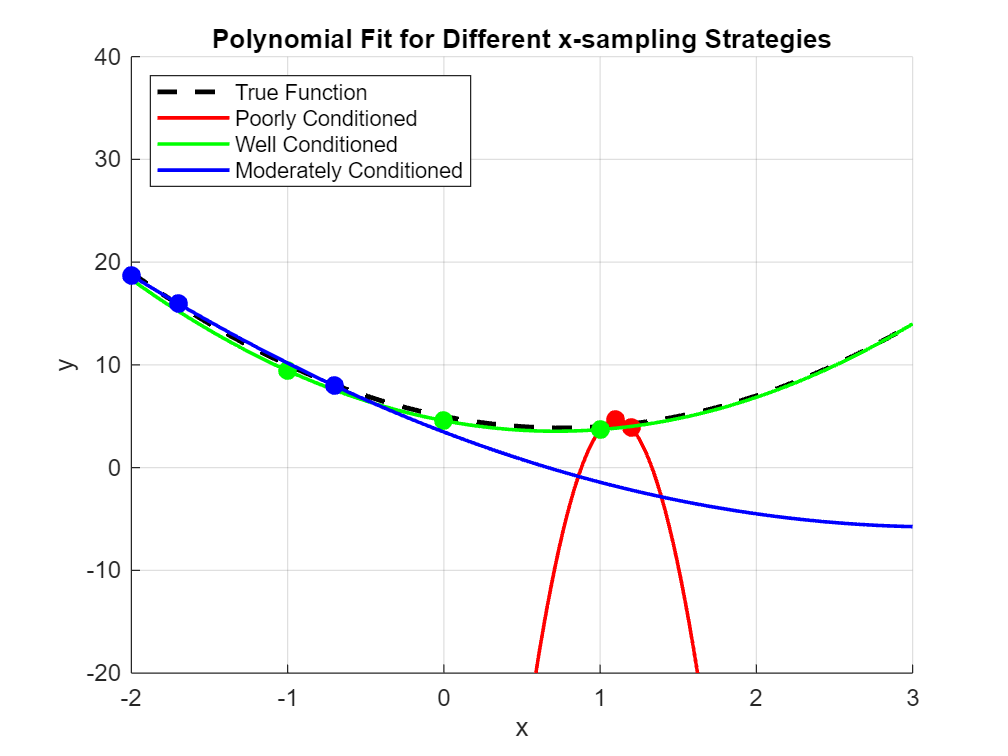

xlabel('x'); ylabel('y');
title('Polynomial Fit for Different x-sampling Strategies');
legend(legend_handles, legend_labels, 'Location', 'northwest');
ylim([-20 40]);
grid on;
hold off;

Finally, we visualize all three computed metrics:

- **Condition number** (sensitivity to noise),

- **Determinant** (volume of the solution space),

- **Estimation error** (how far our fit was from the true parameters).

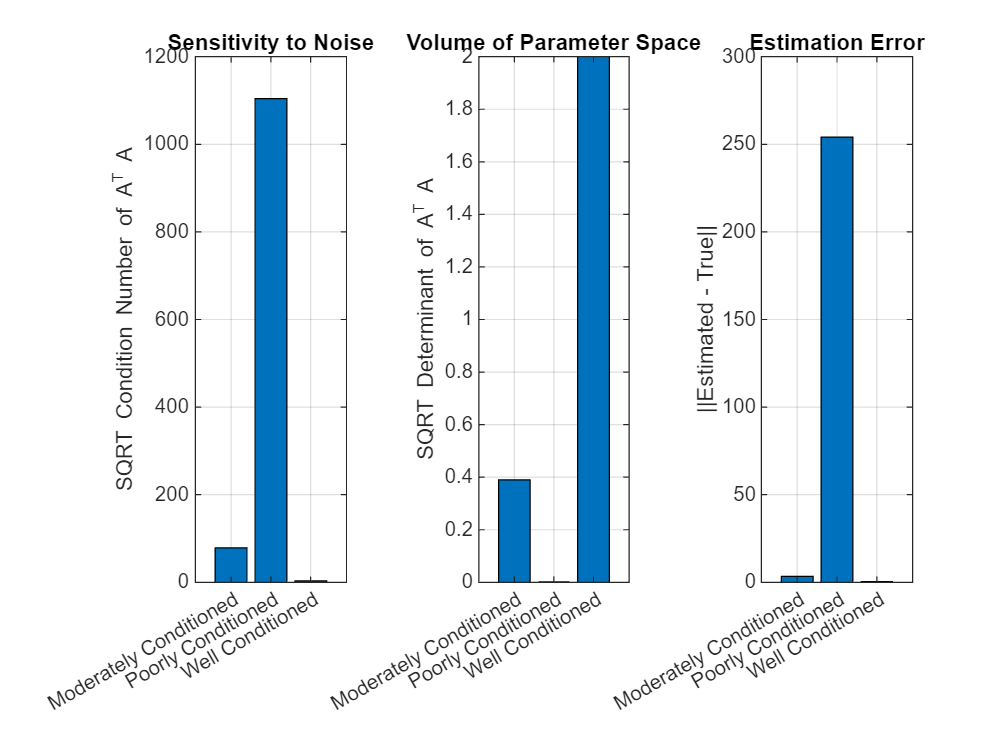

figure(2);

subplot(1,3,1);
bar(categorical(labels), cond_nums);
ylabel('SQRT Condition Number of A^T A');
title('Sensitivity to Noise');
grid on;

subplot(1,3,2);
bar(categorical(labels), det_vals);
ylabel('SQRT Determinant of A^T A');
title('Volume of Parameter Space');
grid on;

subplot(1,3,3);
bar(categorical(labels), errors);
ylabel('||Estimated - True||');
title('Estimation Error');
grid on;